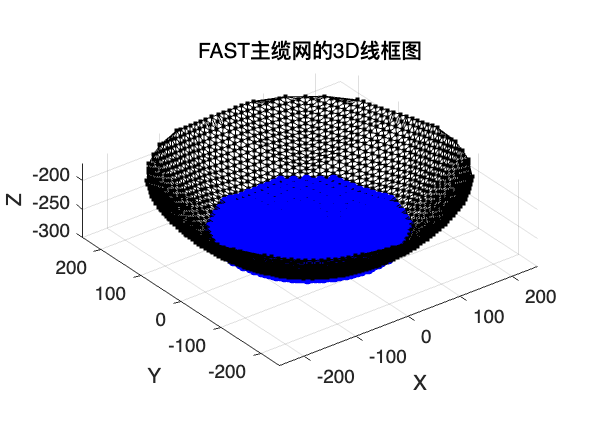


%从CSV文件中读取数据
data = readmatrix('附件1.csv'); % 根据实际的CSV文件名进行调整
nodeIDs = data(:, 1); % 节点ID
x = data(:, 2); % x坐标
y = data(:, 3); % y坐标
z = data(:, 4); % z坐标

% 使用delaunay创建三角网格
tri = delaunay(x, y);

% 绘制3D线框图
figure;
trimesh(tri, x, y, z, 'EdgeColor', 'k', 'FaceColor', 'none');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('FAST主缆网的3D线框图');
axis equal;
grid on;
view(3);

% 标记所有点，z轴小于-259的点使用蓝色标记，稍小的标记大小
hold on;
scatter3(x, y, z, 'k.'); % 所有点用小黑点标记
below_threshold = z < -259;
scatter3(x(below_threshold), y(below_threshold), z(below_threshold), ...
    'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b'); % 蓝色标记z轴小于-259的点
hold off;


% 如果需要显示节点编号，请取消注释
% for i = 1:length(x)
%     text(x(i), y(i), z(i), num2str(nodeIDs(i)), 'Color', 'red', 'FontSize', 8);
% end





